# Simulations and calculations related to Maxwell, 1860 color matching

This script writes out the data that Maxwell 1860 derived as CMFs. These are in Tables VI and IX. The output mat-files are maxwellCMF_obsK and maxwellCMF_obsJ, which are stored in the data subdirectory of this repository.

The Maxwell 1860 paper "On the theory of compound colors".  That paper is discussed in subsequent papers by Judd in 1961 and Zaidi in 1992.  Here we are again, in 2024!

- Judd, D. B. 1961. “Maxwell and Modern Colorimetry.” *The Journal of Photographic Science* 9 (6): 341–52.

- Maxwell, James Clerk, and Qasim Zaidi. 1993. “On the Theory of Compound Colours, and the Relations of the Colours of the Spectrum.” *Color Research and Application* 18 (4): 270–87.

Maxwell uses an interesting method, combining experimental methods and mathematics, to derive the color matching functions for two observers. These were the first CMF measurements, and his paper describes the concepts and methods wonderfully.

Matches made with spinning tops are inthe 1855/1857 paper and not analyzed here.

The CMFs for two subjects (K and J) who matched spectral primaries to a white light are in the 1860 paper.  We analyze those here.

There is another analysis in maxwellMatchWhite.mlx.  That analysis starts with the data from Table IV in the 1860 paper, showing multiple matches of three spectral lights to white.  In the maxwellMatchWhite script, we derive the CMFs directly from Table IV, using modern methods.  The method requires some understanding of linear algebra and null spaces.

## Maxwell's design in the 1860 paper

Maxwell fixed a white and performed a match to the white using mixtures of narrowband lights. The lights were obtained by slits in a prismatic image, derived from an interesting box he built.

Three narrowband lights were chosen as the main primaries. He matched these to the white, repeatedly.

In his design, he would replace one of the primaries with a different narrowband test light, and match the new three lights to the white. Assuming additivity, he computed a relationship between each of the narrowband test lights and the three primaries. Thus, had had a match from about 17 narrowband lights and the three primaries. This was a clever experimental method that enabled him to solve the equations.

The derived CMFs are in Table VI for observer K and Table IX for observer J (maxwell himself, we think).

The same paper also shows the intensities of the matching spectral lights to white. In a separate script, we analyze those data, showing how we come to the same conclusion as Maxwell using modern methods. (maxwellMatch).

## See maxwellJuddWave to get the wavelengths from the Maxwell data in nm.

Judd calculated the wavelengths of the primaries from the values that Maxwell provided. These were estimated by Judd, via a scale factor applied to Maxwell's values. Judd derives the scale factor from the 'Paris inch' units reported by Maxwell.  The analysis is described colloquiually, but in detail, in Judd's 1961 paper.  

We suggest making a small (10 nm) adjustment to these values.  See the script s_maxwellCMF2CIEshift.m in the directory fig01Maxwell of this repository.  This script writes out the original data and Judd's wavelengths.

juddWave = [
    20 663.2
    24 630.2
    28 606.4
    32 583.1
    36 562.5
    40 544.9
    44 528.1
    48 508.6
    52 499.7
    56 486.4
    60 475.1
    64 465.9
    68 456.9
    72 449.4
    76 441.2
    80 434.2];

## CMFs From the 1860 paper

The primaries were wavelengths 24, 44, 68 which is why they are skipped in the rows of the original. I think. I put them in as 1s and 0s.

The first column here is Maxwell's representation of the wavelength. The second column is the intensity of that wavelength. The third-fifth columns are the intensities of the three primaries at wavelengths 24 (630), 44 (528), and 68 (456).

% This is Observer K in Table VI.
obsK6 = [
    20.0000   44.3000   18.6000    0.4000    2.8000
   24.0000    1.0000    1.0000         0         0
   28.0000   16.1000   18.6000    5.8000   -0.1000
   32.0000   22.0000   18.6000   19.3000   -0.1000
   36.0000   25.2000   12.2000   31.4000   -0.8000
   40.0000   26.0000    3.3000   31.4000   -0.2000
   44.0000    1.0000         0    1.0000         0
   46.0000   35.0000   -1.2000   31.4000    0.3000
   48.0000   41.4000   -2.6000   31.4000    3.5000
   52.0000   62.0000   -3.4000   31.4000   30.5000
   56.0000   61.7000   -3.1000   21.0000   30.5000
   60.0000   40.5000   -1.9000    7.7000   30.5000
   64.0000   33.7000   -1.1000    1.1000   30.5000
   68.0000    1.0000         0         0    1.0000
   72.0000   32.3000    0.6000    0.2000   30.5000
   76.0000   44.0000    1.1000    0.7000   30.5000
   80.0000   63.7000    0.3000   -1.8000   30.5000];

waveK6 = interp1(juddWave(:,1),juddWave(:,2),obsK6(:,1));
obsK6(:,1) = waveK6(:);

## Now Obs J in Table IX

obsJ9 = [
   20.0000   44.3000   18.1000   -2.5000    2.3000
   24.0000    1.0000    1.0000         0         0
   28.0000   16.0000   18.1000    6.2000   -0.7000
   32.0000   21.5000   18.1000   25.2000   -0.7000
   36.0000   19.3000    8.1000   27.5000   -0.3000
   40.0000   20.7000    2.1000   27.5000   -0.5000
   44.0000    1.0000         0    1.0000         0
   48.0000   52.3000   -1.4000   27.5000   10.7000
   52.0000   95.0000   -2.4000   27.5000   37.0000
   56.0000   51.7000   -2.2000    4.8000   37.0000
   60.0000   37.2000   -1.2000    0.8000   37.0000
   64.0000   36.7000   -0.2000    0.8000   37.0000
   68.0000    1.0000         0         0    1.0000
   72.0000   35.0000    0.6000   -0.2000   37.0000
   76.0000   40.0000    0.9000    0.5000   37.0000
   80.0000   51.0000    1.1000    0.5000   37.0000];

waveJ9 = interp1(juddWave(:,1),juddWave(:,2),obsJ9(:,1));

## The 2nd column is an overall scale factor

Columns 3-5 are the intensities of the primaries, without accounting for the equalizing scale factor.

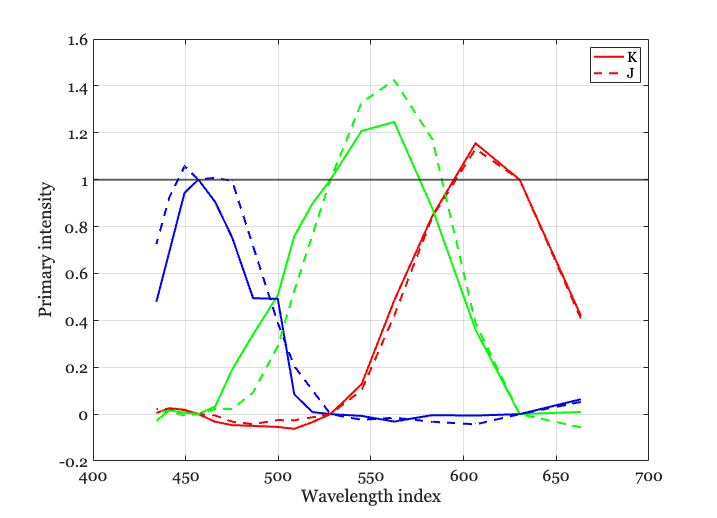

ieNewGraphWin;
lw = 2;
plot(waveK6,obsK6(:,3)./obsK6(:,2),'r','LineWidth',lw); hold on;
plot(waveK6,obsK6(:,4)./obsK6(:,2),'g','LineWidth',lw); hold on;
plot(waveK6,obsK6(:,5)./obsK6(:,2),'b','LineWidth',lw); hold on;

plot(waveJ9,obsJ9(:,3)./obsJ9(:,2),'r--','LineWidth',lw); hold on;
plot(waveJ9,obsJ9(:,4)./obsJ9(:,2),'g--','LineWidth',lw); hold on;
plot(waveJ9,obsJ9(:,5)./obsJ9(:,2),'b--','LineWidth',lw); hold on;
xlabel('Wavelength index');
ylabel('Primary intensity');
grid on;

% Show where the possible primaries are
yline(1,'LineWidth',2);
legend('K','','','J','','','');

## Individual plots

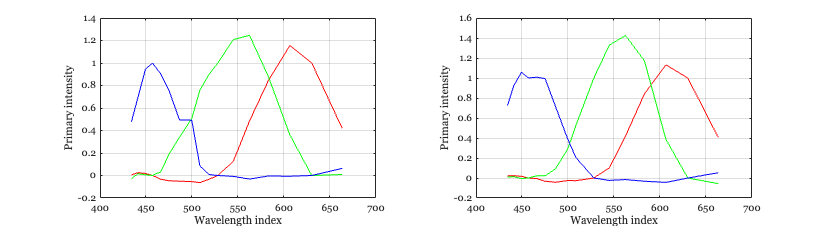

ieNewGraphWin([],'wide');
tiledlayout(1,2);
nexttile;
plot(waveK6,obsK6(:,3)./obsK6(:,2)); hold on;
plot(waveK6,obsK6(:,4)./obsK6(:,2)); hold on;
plot(waveK6,obsK6(:,5)./obsK6(:,2)); hold on;
xlabel('Wavelength index');
ylabel('Primary intensity');
grid on;

nexttile;
plot(waveJ9,obsJ9(:,3)./obsJ9(:,2)); hold on;
plot(waveJ9,obsJ9(:,4)./obsJ9(:,2)); hold on;
plot(waveJ9,obsJ9(:,5)./obsJ9(:,2)); hold on;
xlabel('Wavelength index');
ylabel('Primary intensity');
grid on;

## Save the data out for use by other scripts

disp('Uncomment below here to write out.  Be careful of over-writing!')

Uncomment below here to write out.  Be careful of over-writing!


%{
    B = obsJ9(:,3)./obsJ9(:,2);
    G = obsJ9(:,4)./obsJ9(:,2);
    R = obsJ9(:,5)./obsJ9(:,2);
    wave = waveJ9;
    save('maxwellCMF_obsJ','wave','R','G','B');

    B = obsK6(:,3)./obsK6(:,2);
    G = obsK6(:,4)./obsK6(:,2);
    R = obsK6(:,5)./obsK6(:,2);
    wave = waveK6;
    save('maxwellCMF_obsK','wave','R','G','B');
%}

## END